# Ejercicio Nº9

clear;clc;

# Respuesta al impulso

syms C1 C2 C3 C4 C5 s R1 R2 R3 R4 R5 E1 v1 v2 v3 v4 v5;

La matriz de admitancias

Y=[1/R1+s*C1+1/R2 -1/R2 0 0 0; -1/R2 1/R2+s*C2+1/R3 -1/R3 0 0;0 -1/R3 1/R3+s*C3+1/R4 -1/R4 0; 0 0 -1/R4 1/R4+s*C4+1/R5 -1/R5; 0 0 0 -1/R5 1/R5+s*C5]

$$Y = \left(\begin{array}{ccccc} C_{1}\,s+\frac{1}{R_{1}}+\frac{1}{R_{2}} & -\frac{1}{R_{2}} & 0 & 0 & 0\\ -\frac{1}{R_{2}} & C_{2}\,s+\frac{1}{R_{2}}+\frac{1}{R_{3}} & -\frac{1}{R_{3}} & 0 & 0\\ 0 & -\frac{1}{R_{3}} & C_{3}\,s+\frac{1}{R_{3}}+\frac{1}{R_{4}} & -\frac{1}{R_{4}} & 0\\ 0 & 0 & -\frac{1}{R_{4}} & C_{4}\,s+\frac{1}{R_{4}}+\frac{1}{R_{5}} & -\frac{1}{R_{5}}\\ 0 & 0 & 0 & -\frac{1}{R_{5}} & C_{5}\,s+\frac{1}{R_{5}} \end{array}\right)$$

Is=[E1/R1;0;0;0;0];
x=[v1;v2;v3;v4;v5];
Y\(Is)==x;
eqs=Y*x==Is;
solu=solve(eqs);

Reemplazando los valores del circuito

C1=0.1;C2=0.1;C3=0.1;C4=0.1;C5=0.1;R1=1;R2=1;R3=1;R4=1;R5=1;E1=1;

La función de transferencia $ H(s)=V5(s)/E(s)$

v5s=subs(solu.v5)

$$v5s = \frac{1}{\frac{s^{5}}{100000}+\frac{9\,s^{4}}{10000}+\frac{7\,s^{3}}{250}+\frac{7\,s^{2}}{20}+\frac{3\,s}{2}+1}$$

v5t=vpa(rewrite(ilaplace(v5s),'exp'),4)

$$v5t = 2.72\,{\mathrm{e}}^{-17.15\,t}+0.5539\,{\mathrm{e}}^{-36.83\,t}+1.014\,{\mathrm{e}}^{-0.8101\,t}-2.5\,{\mathrm{e}}^{-6.903\,t}-1.788\,{\mathrm{e}}^{-28.31\,t}$$

# Respuesta al pulso con método Backward Euler

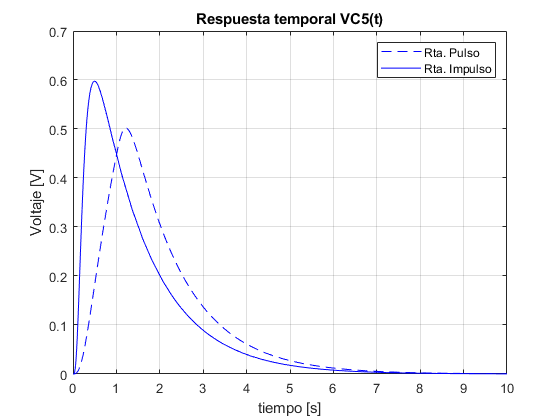

vc1=0;vc2=0;vc3=0;vc4=0;vc5=0;
Xant=[vc1;vc2;vc3;vc4;vc5];
ti=0;
tf=10;
h=0.01;
M=[C1 0 0 0 0; 0 C2 0 0 0; 0 0 C3 0 0; 0 0 0 C4 0; 0 0 0 0 C5];
N=[1/R1+1/R2 -1/R2 0 0 0; -1/R2 1/R2+1/R3 -1/R3 0 0; 0 -1/R3 1/R3+1/R4 -1/R4 0; 0 0 -1/R4 1/R4+1/R5 -1/R5; 0 0 0 -1/R5 1/R5];
solu=[];
it=1;
for i= ti:h:tf
    %Fuente variable
    if i<1
        E(it,1)=1;
    else
        E(it,1)=0;
    end

    %Se calcula el valor de la matriz u para cada punto 
    u=[E(it,1)/R1;0;0;0;0];
    
    X=((((1/h).*M)+N)\u) + ((((1/h).*M)+N)\((1/h).*M)*Xant);
    
    solu=[solu X];
    Xant=X;
    it=it+1;
end
t=ti:h:tf;
clf;
plot(t,solu(5,:),'--b')
hold on
fplot(v5t,[0,10],'-b')
ylim([0,0.7])
grid;
legend({'Rta. Pulso','Rta. Impulso'})
title('Respuesta temporal VC5(t)')
xlabel('tiempo [s]')
ylabel('Voltaje [V]')